#### linear system

1. transfer function

num=[1];
den=[0.5 1];
sys_tf=tf(num,den)


sys_tf =
 
      1
  ---------
  0.5 s + 1
 
Continuous-time transfer function.



pole(sys_tf)

ans = -2

zero(sys_tf)


ans =

  0×1 empty double column vector



2. state space

A=[-3 -2.5; 2 0];
B=[2;0];
C=[0.5 1];
D=0;
sys_ss=ss(A,B,C,D)


sys_ss =
 
  A = 
         x1    x2
   x1    -3  -2.5
   x2     2     0
 
  B = 
       u1
   x1   2
   x2   0
 
  C = 
        x1   x2
   y1  0.5    1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



the system will be saved as "LTI objects" in workspace. They can switch each other.

%switch each other
sys_tf_new=tf(sys_ss)


sys_tf_new =
 
      s + 4
  -------------
  s^2 + 3 s + 5
 
Continuous-time transfer function.



sys_ss_new=ss(sys_tf)


sys_ss_new =
 
  A = 
       x1
   x1  -2
 
  B = 
       u1
   x1   2
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



There we can analyze the performace of the system.

1. stability analysis. 2. Time domain response 3. Frequency domain response

Then plot a ploes-zeros map, Time response (step, stepinfo, impulse,lsim), Bode diagram (bode, bodemag, margin, dcgain, bandwidth, evalfr) and Nyquist map.

These analysis can be finished by the linear system analyze tool

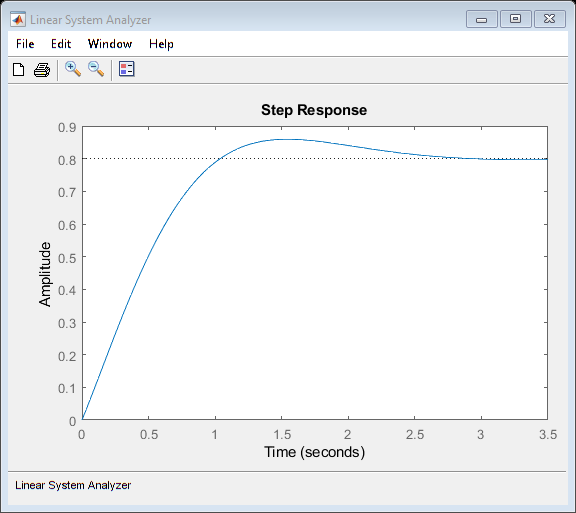

sys=sys_ss;
linearSystemAnalyzer(sys)

#### Use Simulinnk to build Control Target

parameters:

Motor inertia (J1); Load inertia (J2); Torsional spring (k); Motor torque (T); Damping (b1, b2, b12)

1.White box

2.Black box

3. Gray box

for the electric equation:


$$u(t)=E_m+R_0\cdot i(t)+u_1(t)

$$



$$i(t)=C_1\cdot \dot u_1(t)+u_1(t)/R_1$$


Laplas transform into:


$$U(s)=E_m+R_0\cdot I(s)+U_1(s)$$



$$I(s)=C_1s\cdot U_1(s)+U_1(s)/R_1$$


Aquire the transform function:


$$U(s)=E_m+R_0\cdot I(s)+\frac {R_1\cdot I(s)} {R_1C_1s+1}$$


Use the experience data to estimate paraneters.

#### Simscape

To build physical model: Power System, Multibody, Fluids, Driveline and Electronics.

doc simscape

#### Simulink Control Algorithm Design

Linearize Simulink Model at Model Operating Point

PID Controller Tuning in Simulink

Modeling Computational Delay and Sampling Effects

#### System Recognetion

Black box--->Linear model

To a complex nonlinear model, use the step response

doc systemIdentification

Based on FAR to compute the fixed points

JT9D_setup_everything_SS;
FAR_SS=[0.013 0.014 0.015 0.016 0.017 0.018 0.019 0.020]; %different fuel air rate
Wf_SS=zeros(1,8); 
LPS_SS=zeros(1,8);
HPS_SS=zeros(1,8);
P3_SS=zeros(1,8);
T45_SS=zeros(1,8);
for i=1:8
    MWS.Input.FARin=FAR_SS(i);
    sim('JT9D_Model_SS.slx')
    Wf_SS(i)=MWS.Input.FARin*S3.W.Data(1000);
    LPS_SS(i)=LPCData.Nmech.Data(100);
    HPS_SS(i)=HPCData.Nmech.Data(100);
    P3_SS(i)=S3.Pt.Data(100);
    T45_SS(i)=S45.Tt.Data(100);
end

No system or file called 'JT9D_Model_SS.slx' found.

At the fixed point, give it a 5% fuel step

load ('JT9D_Model_BUs.mat');
Wf_init=WS_SS(5);
LPS_init=LPS_SS(5);
HPS_init=HPS_SS(5);
P3_init=P3_SS(5);
T45_init=T45_SS(5);
Wf_step=0.05*Wf_init;
sim('JT9D_Model_Dyn.slx')
plot(tout,Wf_Dyn)
xlab('Time(s)')
ylabel('Wf(kg/s)')
grid

System Recognition

data1=iddata([LPS_Dyn-LPS_init HPS-Dyn-HPS_init],Wf_Dyn-Wf_init,0.04);
odefun = 'linmdl1'; 
parameters={0;0;0;0;0;0};
Ts=0.04;
init_sys=idgrey(odefun,parameters,'d',Ts);
sys1=grayest(data1,init_sys);
data2=iddata([LPS_Dyn-LPS_init HPS_Dyn-HPS_init P3_dyn-P3_init T45_Dyn-T45_init]);
odefun='linmdl2';
parameters={sys1.A(1,1);sys1.A(1,2); sys1.A(2,1); sys1.A(2,2); sys1.B(1); sys1.B(2)};
Ts=0.04

#### Matlab App for Developed Control Method

#### Matlab Auto Coder

1. MATLAB Coder

2. SIMULINK Coder

3. Embedded Coder (Automatically generate C and C++ optimized for embedded system)

Eg:

rtwdemo_pmsmfoc_system